# Gappy experiments

## PDE Settings

### Spatial Dimensionality

Nx = 1000;

### Diffusion

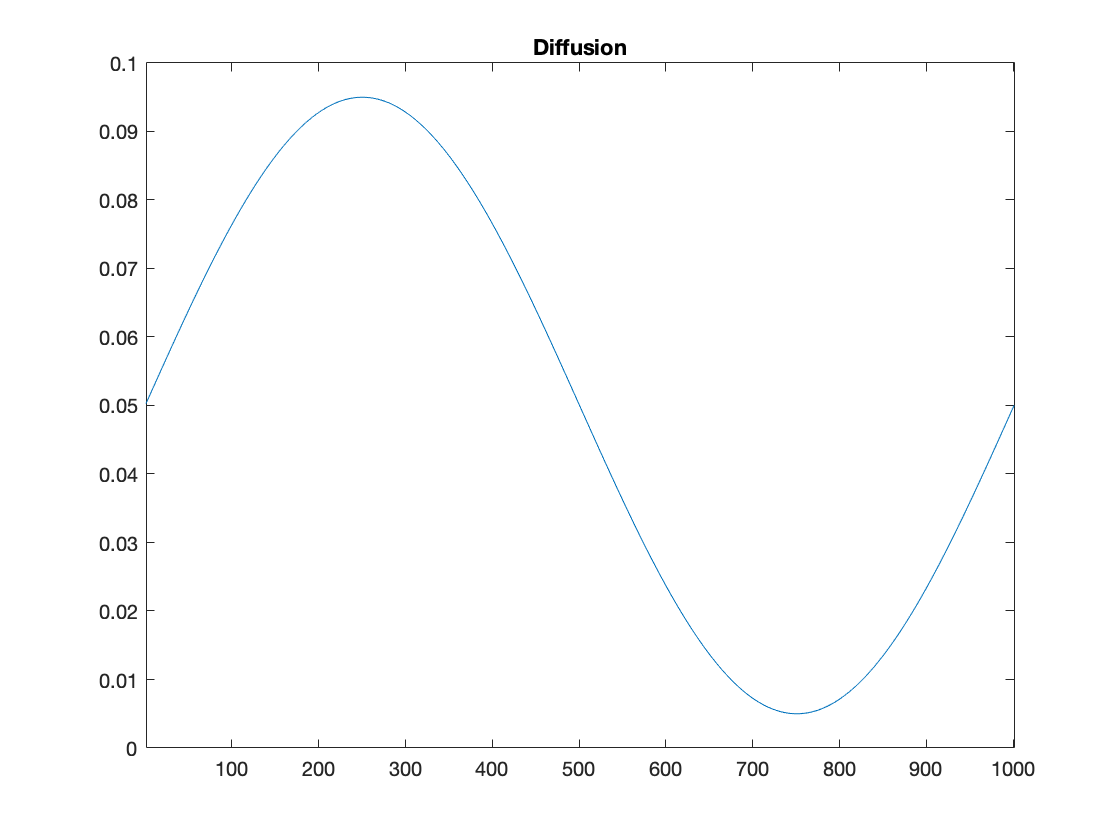

k =1; 
D  = genDiffusion(Nx,0.9,1,0.5e-1, @(u) [1+u^2*k,2*u*k]);

plot(axes(figure),1:(Nx+1),D.val); title('Diffusion');
xlim([1,Nx+1]);

### Initial and Boundary Conditions

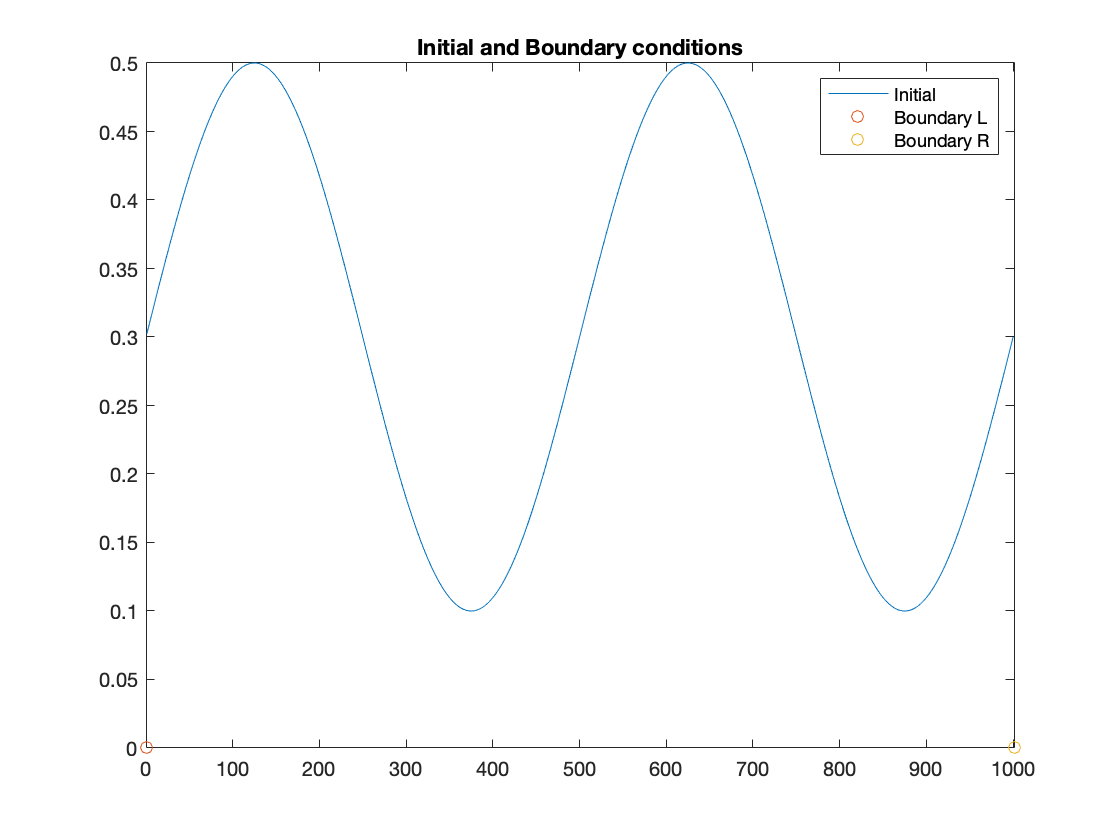

bc = genBC(1,[0,0]);
x0 = genInit(Nx,0.2,2,0.3);

plot(axes(figure),1:Nx,x0,'-',0,bc.val(1),'o',Nx+1,bc.val(2),'o');
title('Initial and Boundary conditions');
xlim([0,Nx+1]); legend({'Initial','Boundary L','Boundary R'});

### Problem Constructors

makeFOM = @(q,name) genProblem(name,Nx,genParam(D,bc,q),x0);
makeROM_I = @(name,q,encoder) genProblem(name,Nx,genParam(D,bc,q),x0,encoder);
makeROM_II = @(name,q,encoder,nfa_res,nfa_jac) genProblem(name,Nx,genParam(D,bc,q),x0,encoder,nfa_res,nfa_jac);

### Temporal Dimensionality

T = 1;
Nt = 100;
dt = T/Nt;

## Nonlinear Solver Settings

newton_param = struct(...
    'iters'    , 10,...
    'iters_min', 3,...
    'tol'      , 1e-4,...
    'tol_rel'  , 1e-4,...
    'tol_g'    , 1e-4,...
    'tol_rel_g', 1e-4 ...
    );

nlin_newton = @(x,Res,Jac) newton(x,Res,Jac,newton_param);

## FOM

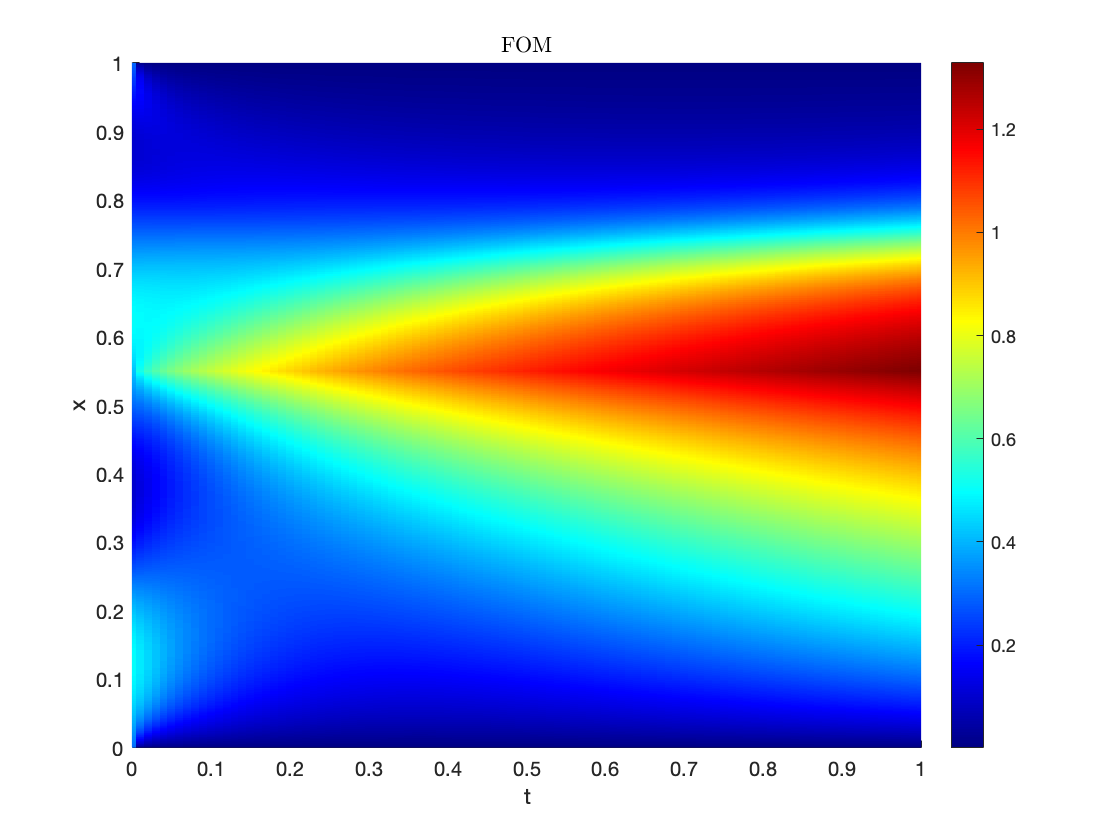

q = genSource(Nx,0.55,1e+2*5);
FOM = solveDif(T,Nt,makeFOM(q,'FOM'),nlin_newton);

plotSol(axes(figure),FOM);

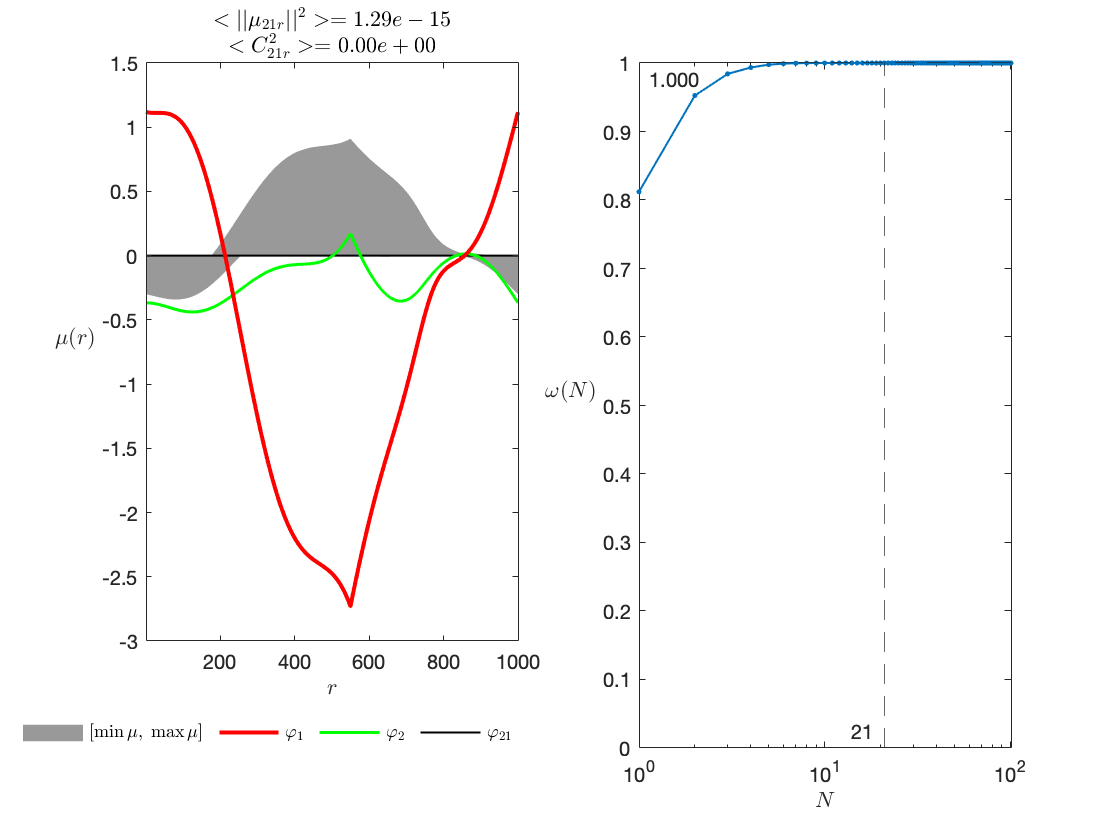


[X,W,Jw,Y] = collectSolData(FOM);
y0 = Y(:,1);

FOM.pod = PCA(FOM.X,21,'init',x0);
FOM.pod.plotSummary(figure());

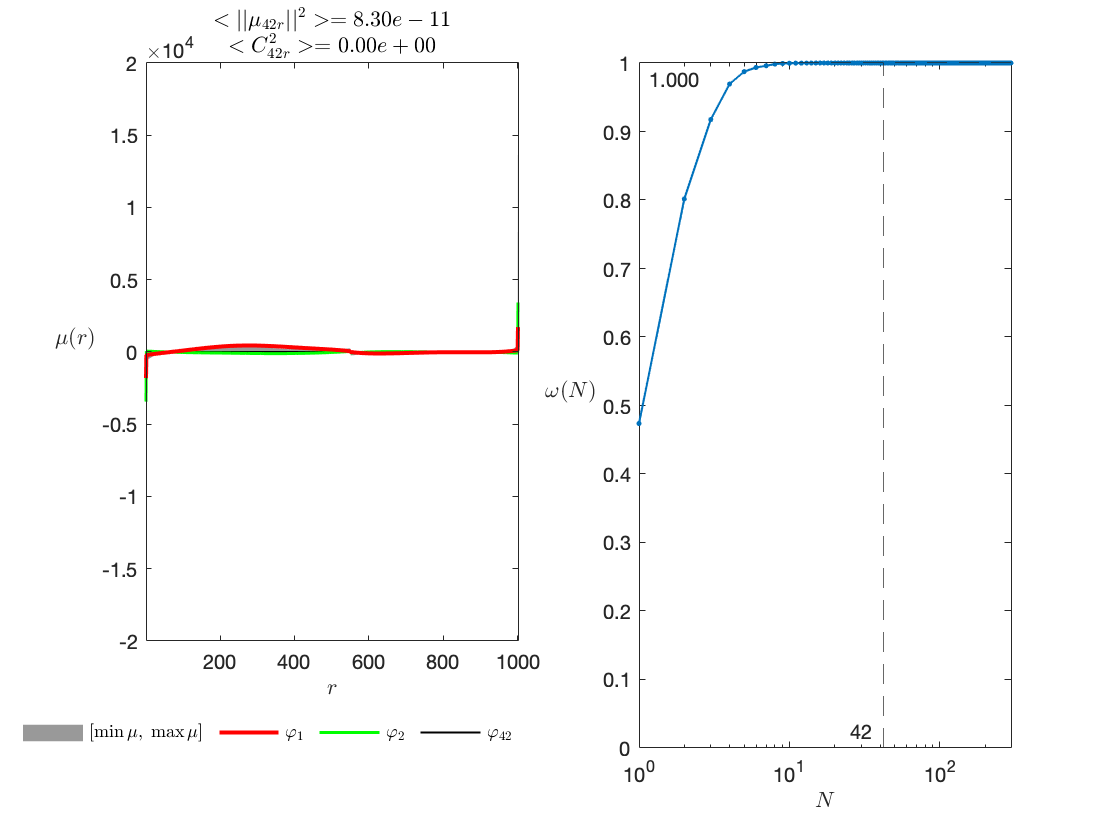


FOM.gappy = PCA(W,FOM.pod.npc()*2);
FOM.gappy.plotSummary(figure());


Q = repmat(q.val,1,Nt+1);
Q = [Q;zeros(size(Y))];

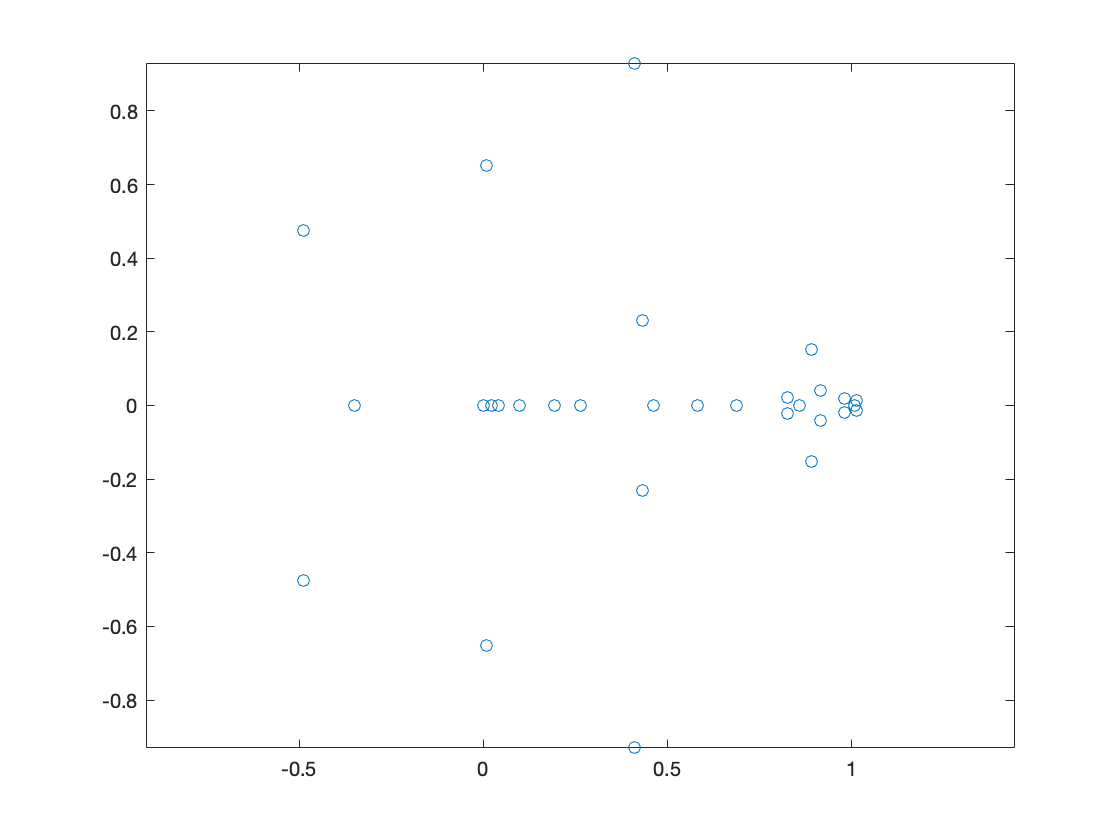

Z = [X;Y];
Z1 = merge_dmd_data(1,Z);
Z2 = merge_dmd_data(2,Z);
Q1 = merge_dmd_data(1,Q).*dt;

rk = 30;
%[A,Psi,Lambda,v] = DMD_databook(Z1,Z2-Q1,rk);
[A,Psi,Lambda] = dmds(Z1,Z2-Q1,rk);
% [A,Psi,Lambda] = dmd(Z1,Z2-Q1);

plot(axes(figure),Lambda,'o');
axis equal;


G = calcGreenFDE(Psi,Lambda,Nt,Z(:,1),Q1(:,1));
norm(imag(G))

ans =      3.029669484898962e-09


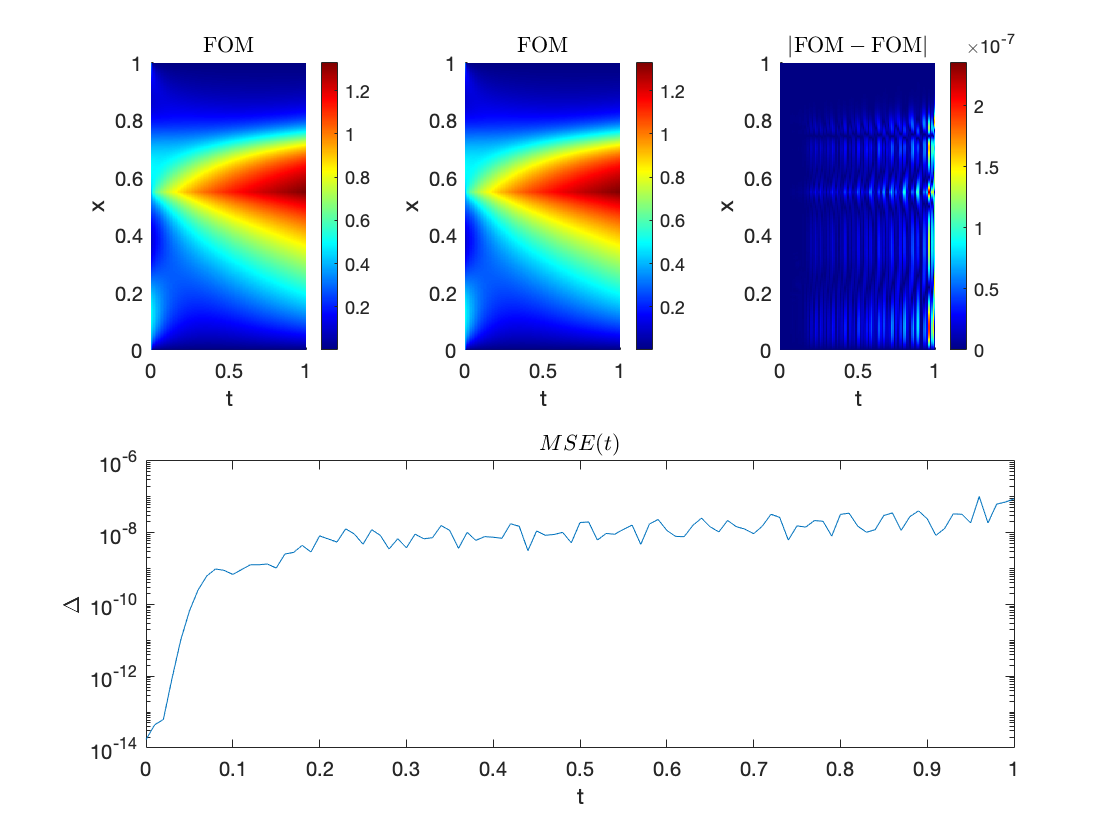

G = real(G);

DMD = FOM;
DMD.X = G(1:Nx,:);
plotComp(figure(),FOM,DMD);

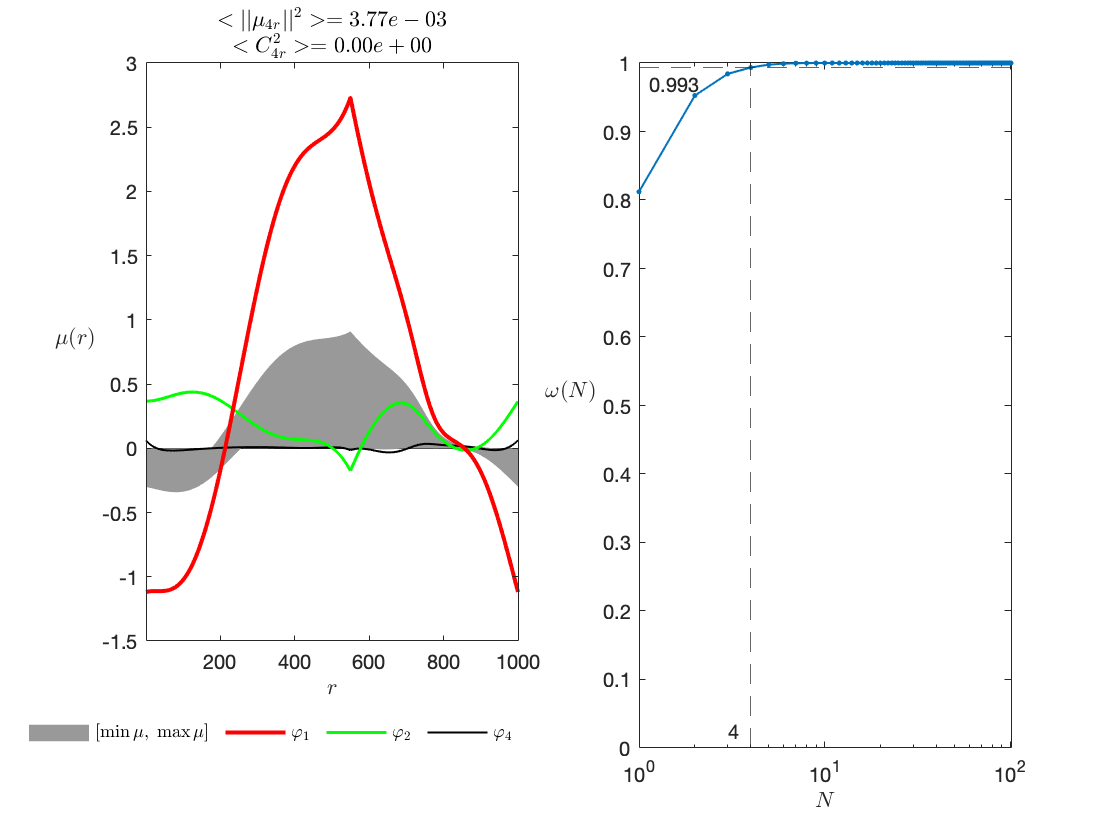


DMD.pod = PCA(DMD.X,0.99,'init',x0);
DMD.pod.plotSummary(figure(),'data',X);

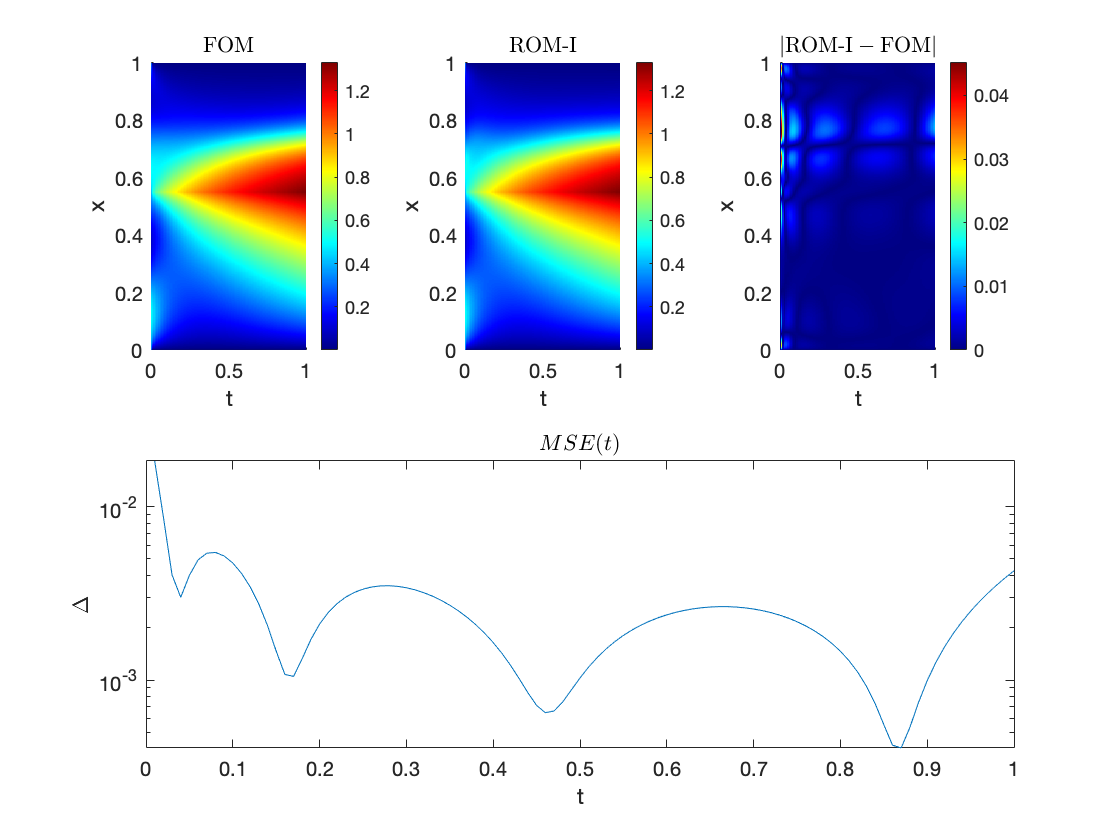

DMD.encoder = DMD.pod.genEncoder();

DMD.rom.I = makeROM_I('ROM-I',q,DMD.encoder);

nlin.gauss = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param,DMD.pod.genEncoder().decjac);

DMD.rom.I = solveDif(T,Nt,DMD.rom.I,nlin.gauss);
DMD.rom.I.X = DMD.pod.decode(DMD.rom.I.X);
plotComp(figure(),FOM,DMD.rom.I);

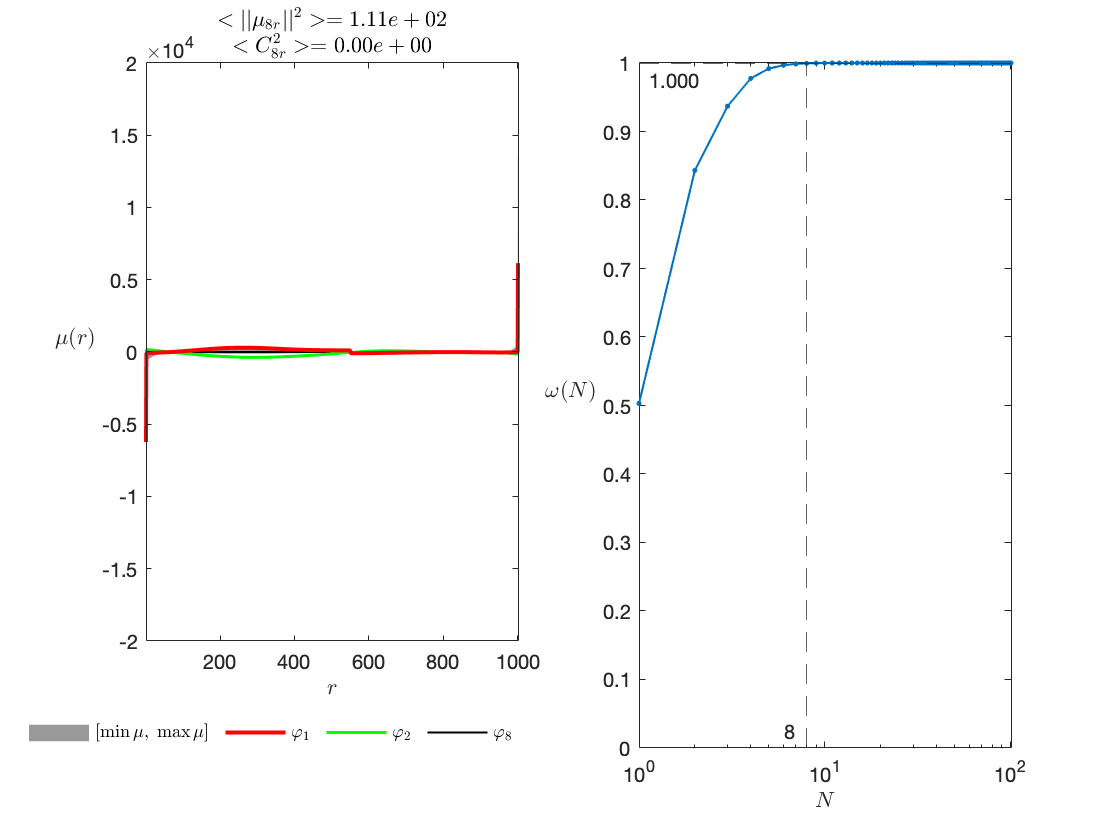

k_max = max([FOM.nlin.iters],[],'all');

DMD.gappy = PCA(Y,DMD.pod.npc()*2);
DMD.gappy.plotSummary(figure(),'data',W);

idx = [DMD.gappy.calcGreedy(20),q.pos]

idx =            1           2           3           4          15          16          52          53          54         261         283         284         285         389         390         510         511         926         927        1001         550


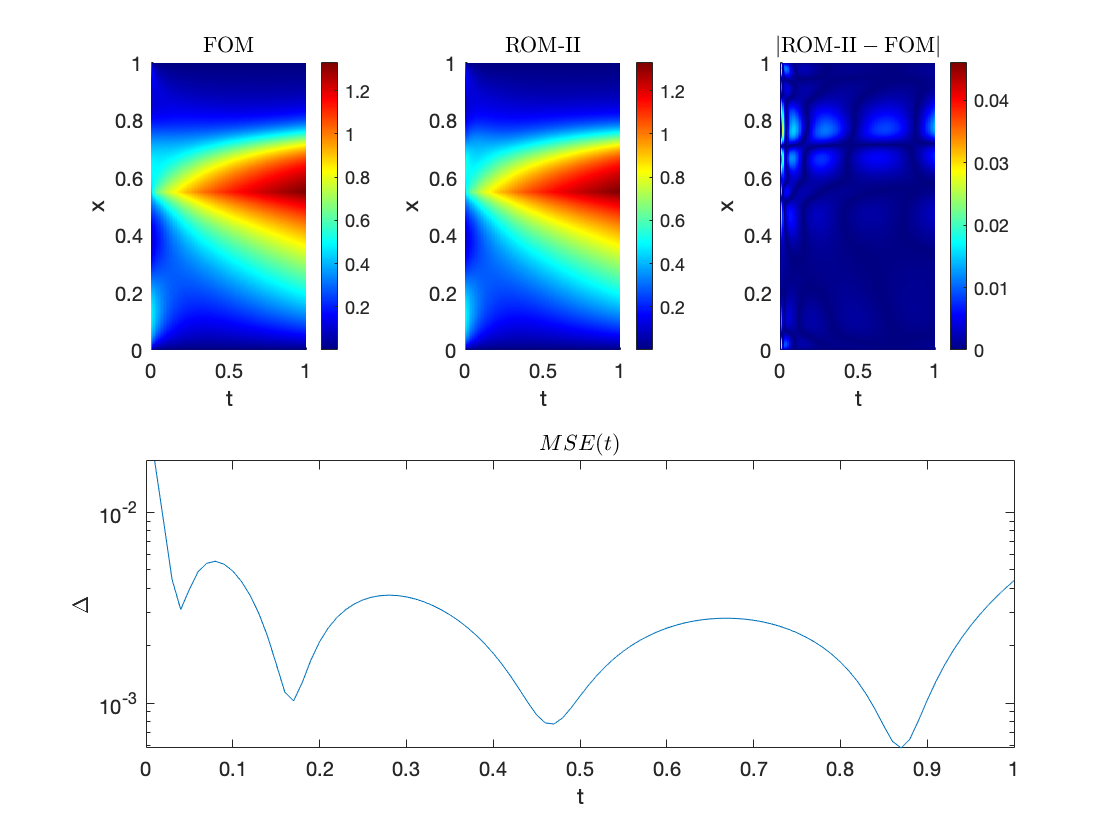

DMD.gappy = DMD.gappy.buildGappy(idx);
DMD.nfa = DMD.gappy.genNFA();

DMD.rom.II = genProblem('ROM-II',Nx,genParam(D,bc,q),x0,DMD.encoder,DMD.nfa);
DMD.rom.II = solveDif(T,Nt,DMD.rom.II,nlin.gauss);
DMD.rom.II.X = DMD.pod.decode(DMD.rom.II.X);
plotComp(figure(),FOM,DMD.rom.II);

q_train = {genSource(Nx,0.5,1e+2*5),...
           genSource(Nx,0.6,1e+2*5)};
q_i_min = q_train{1}.pos;
q_i_max = q_train{2}.pos;

Z1 = [];
Z2 = [];
Q1 = [];
for i = 1:length(q_train)
    TRAIN(i) = solveDif(T,Nt,makeFOM(q_train(i),'TRAIN'),nlin_newton);
    X = TRAIN(i).X;
    
    [~,~,~,Y] = collectSolData(TRAIN(i));
    
    Q = repmat(q_train{i}.val,1,Nt+1);
    Q = [Q;zeros(size(Y))];
    
    Z = [X;Y];
    Z1 = [Z1,merge_dmd_data(1,Z)];
    Z2 = [Z2,merge_dmd_data(2,Z)];
    Q1 = [Q1,merge_dmd_data(1,Q).*dt];
end
z0 = Z1(:,1);
y0 = Z1(Nx+1:end,1);
q_test = genSource(Nx,0.55,1e+2*5);
FOM = solveDif(T,Nt,makeFOM(q_test,'FOM'),nlin_newton);

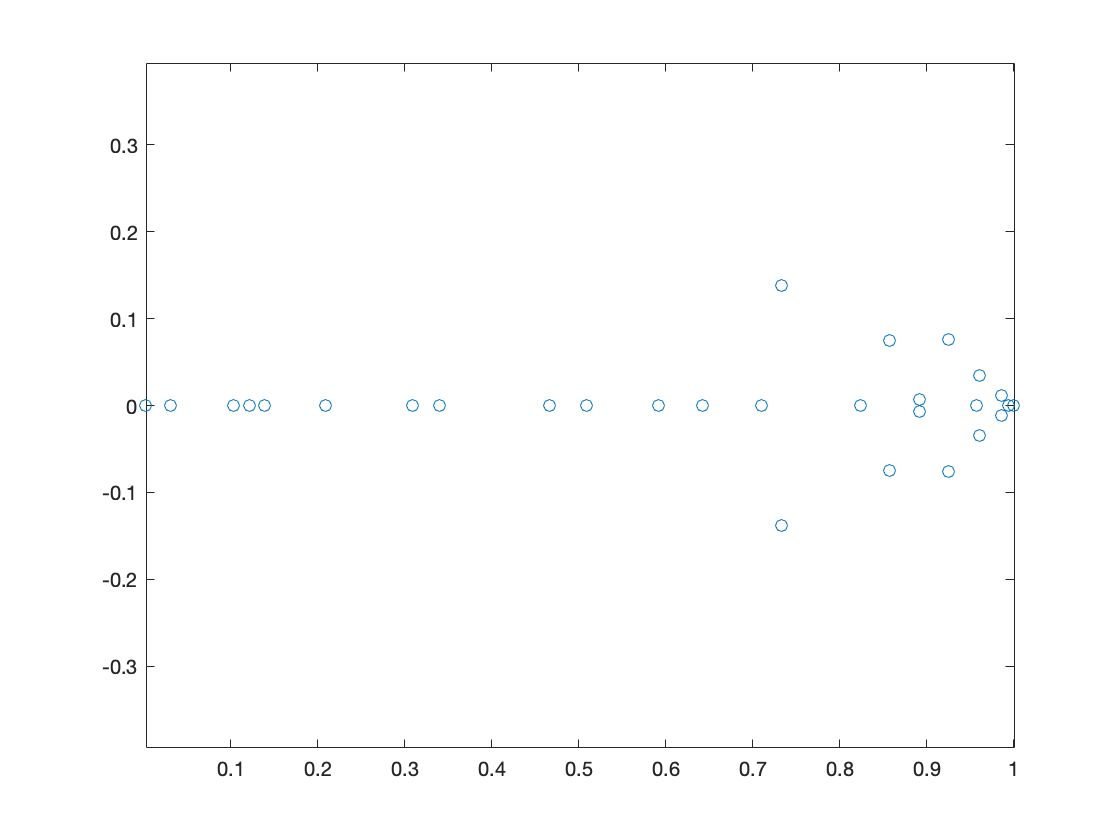

rk = 30;
%[A,Psi,Lambda,v] = DMD_databook(Z1,Z2-Q1,rk);
[A,Psi,Lambda] = dmds(Z1,Z2-Q1,rk);
% [A,B] = DMDc(Z1,Z2,full(Q1));
% [Psi,Lambda] = eig(A,'vector');
% Lambda(abs(Lambda) < 1e-5) = 0;
% Lambda = diag(Lambda);

% [A,Psi,Lambda] = dmd(Z1,Z2-Q1);

plot(axes(figure),Lambda,'o');
axis equal;


p_test = [q_test.val;zeros(size(y0))];

G = calcGreenFDE(Psi,Lambda,Nt,z0,p_test.*dt);
norm(imag(G))

ans =      1.514423380460391e-10


G = real(G);

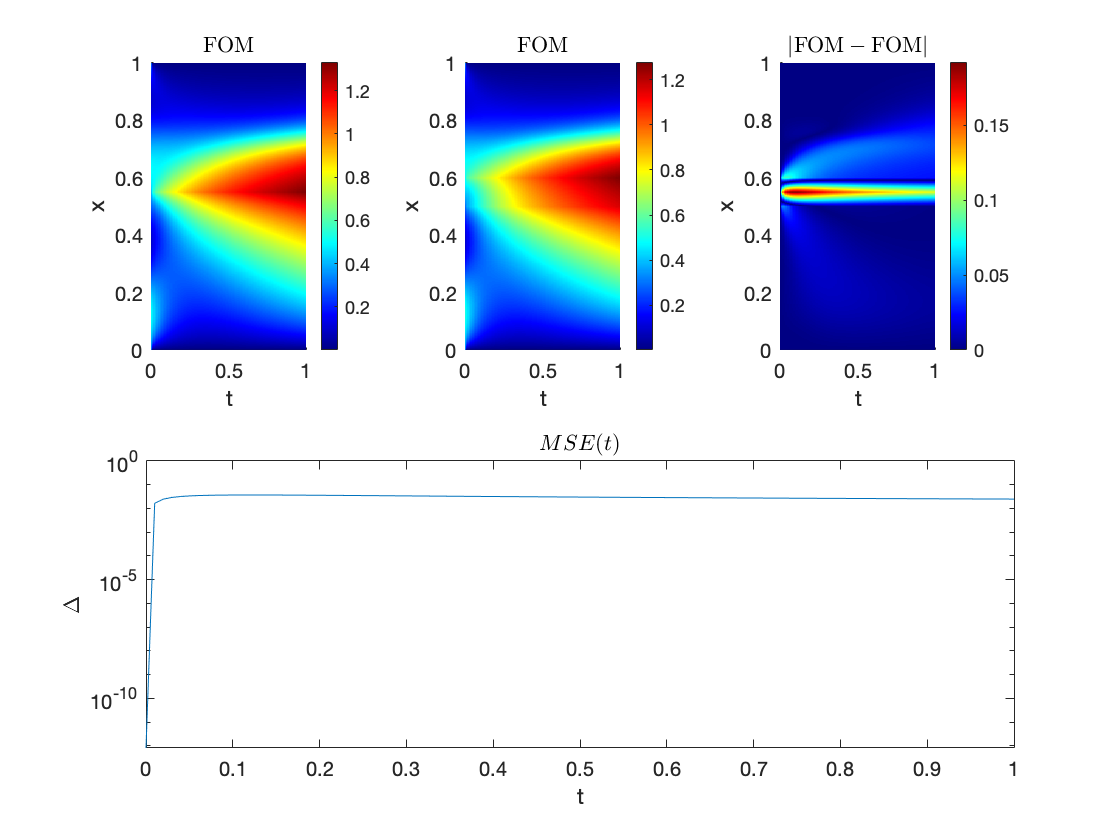

DMD = FOM;
DMD.X = G(1:Nx,:);
plotComp(figure(),FOM,DMD);

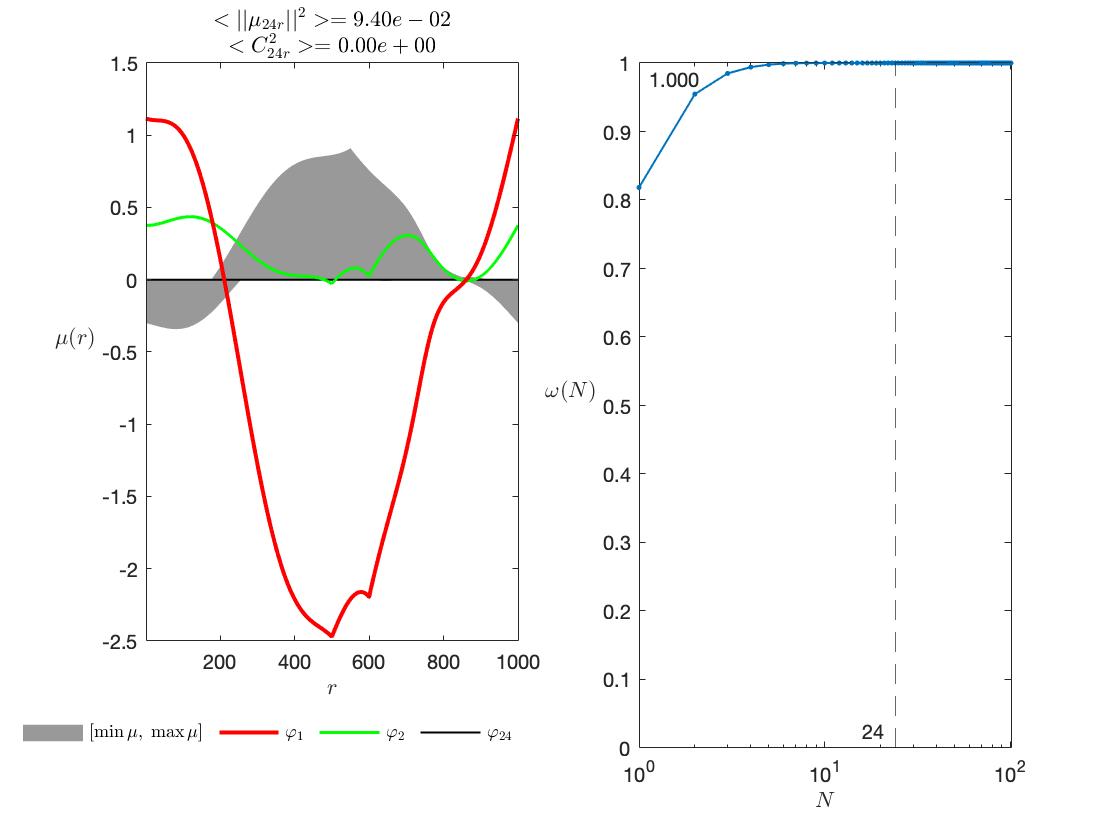


DMD.pod = PCA(DMD.X,24,'init',x0);
DMD.pod.plotSummary(figure(),'data',FOM.X);

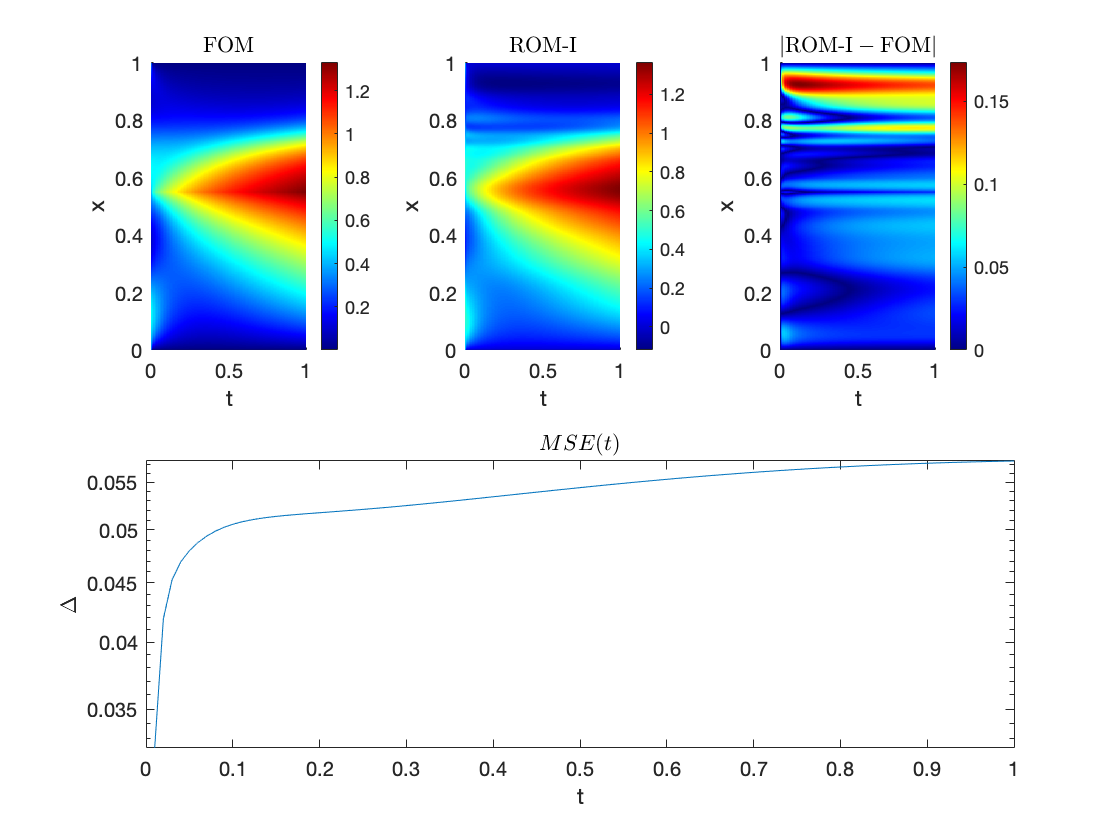

DMD.encoder = DMD.pod.genEncoder();

DMD.rom.I = makeROM_I('ROM-I',q_test,DMD.encoder);

nlin.gauss = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param,DMD.pod.genEncoder().decjac);

DMD.rom.I = solveDif(T,Nt,DMD.rom.I,nlin.gauss);
DMD.rom.I.X = DMD.pod.decode(DMD.rom.I.X);
plotComp(figure(),FOM,DMD.rom.I);

Space-time deformations

Let $y=\alpha \;x$

then, if $u_t + \kappa u_x = 0$


$$\tau = \alpha t$$



$$\tilde{u}_\tau + \kappa \tilde{u}_y = 0$$



$$\tilde{u}(y,\tau) = u(x.t)$$


So, if we shrink space to match new source term position, we also should shrink time as well. Different rescaling from the different sides of source position leads to shorter dataset.

Deform solution to match source terms

ix = griddedInterpolant([1,q_test.pos],[1,q_i_min]);
iu = griddedInterpolant(1:q_i_min,TRAIN(i).X(1:q_i_min,:));
X = iu(ix(1:q_test.pos));


$$y = \alpha x$$



$$\tau = \beta t$$



$$u_t \tilde{} u_{xx}$$



$$\beta u_\tau \tilde{} \alpha^2 u_{yy}$$



$$\beta = \alpha^2$$


U = TRAIN(1).X;
q_old = TRAIN(1).param.q.pos;
U_left = U(1:q_old,:);
U_right = U(q_old:end,:);

% space deformation
q_new = q_test.pos;
U_left = deform(U_left,q_new);
U_right = deform(U_right,Nx-q_new+1);

U_new = [U_left;U_right(2:end,:)];

% time deformation
space_scale_left = q_new / q_old;
time_scale_left = space_scale_left^2;

space_scale_right = (Nx-q_new+1) / (Nx-q_old+1);
time_scale_right = space_scale_right^2;

time_scale_all = time_scale_left/time_scale_right;
size_old = size(U_left,2);
U_left = deform(U_left',round(size_old*time_scale_all))';
U_left = U_left(1:end-1,1:size_old);

U_new =[U_new,[U_left;U_right]];

U = TRAIN(2).X;
q_old = TRAIN(2).param.q.pos;
q_new = q_test.pos;

U_left = U(1:q_old,:);
U_right = U(q_old:end,:);

% space deformation
U_left = deform(U_left,q_new);
U_right = deform(U_right,Nx-q_new+1);

U_new =[U_new,[U_left;U_right(2:end,:)]];

% time deformation
space_scale_left = q_new / q_old;
time_scale_left = space_scale_left^2;

space_scale_right = (Nx-q_new+1) / (Nx-q_old+1);
time_scale_right = space_scale_right^2;

time_scale_all = time_scale_right/time_scale_left;
size_old = size(U_right,2);
U_right = deform(U_right',round(size_old*time_scale_all))';
U_right = U_right(2:end,1:size_old);
% 
U_new =[U_new,[U_left;U_right]];

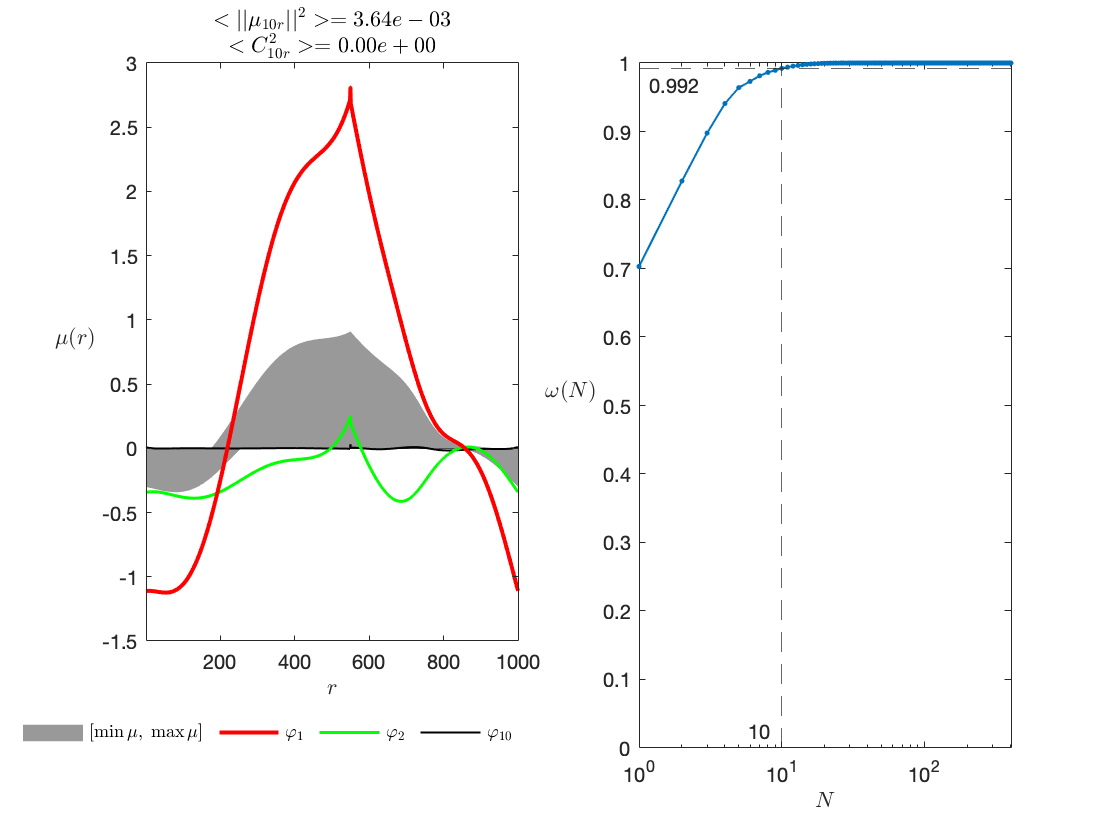

INTERP = FOM;
INTERP.X = U_new;
% plotComp(figure(),FOM,INTERP);

INTERP.pod = PCA(INTERP.X,0.99,'init',x0);
INTERP.pod.plotSummary(figure(),'data',FOM.X);

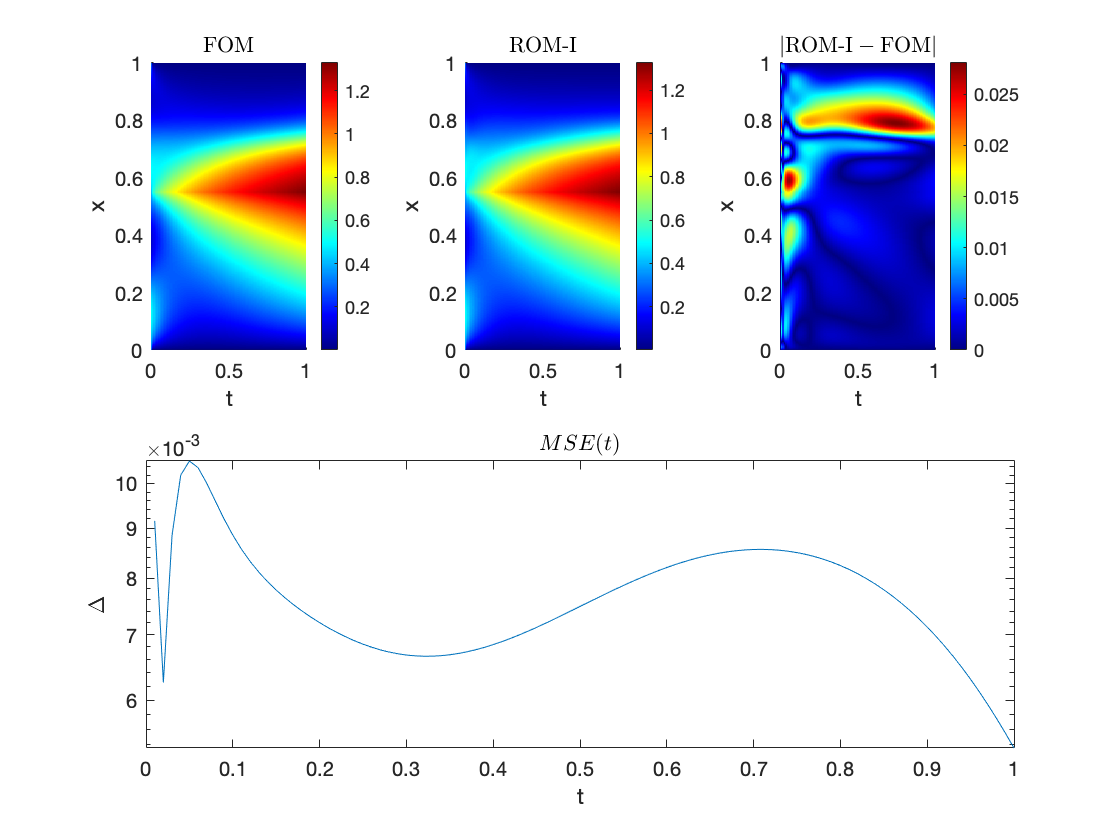

INTERP.encoder = INTERP.pod.genEncoder();
 
INTERP.rom.I = makeROM_I('ROM-I',q_test,INTERP.encoder);

nlin.gauss = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param,INTERP.pod.genEncoder().decjac);

INTERP.rom.I = solveDif(T,Nt,INTERP.rom.I,nlin.gauss);
INTERP.rom.I.X = INTERP.pod.decode(INTERP.rom.I.X);
plotComp(figure(),FOM,INTERP.rom.I);

#### h-refinement


$$\Phi 
= \left[ \matrix{ \Phi_1 \cr \dots \cr \Phi_2} \right] 
\\
u = \Phi a
= \left[ 
\matrix{ \Phi_1 \cr 0 \cr 0}
 \matrix{ 0 \cr 1 \cr 0} 
 \matrix{ 0 \cr 0 \cr \Phi_2} 
 \right] 
 \left[  \matrix{ a \cr u_q \cr a}  \right] 
$$


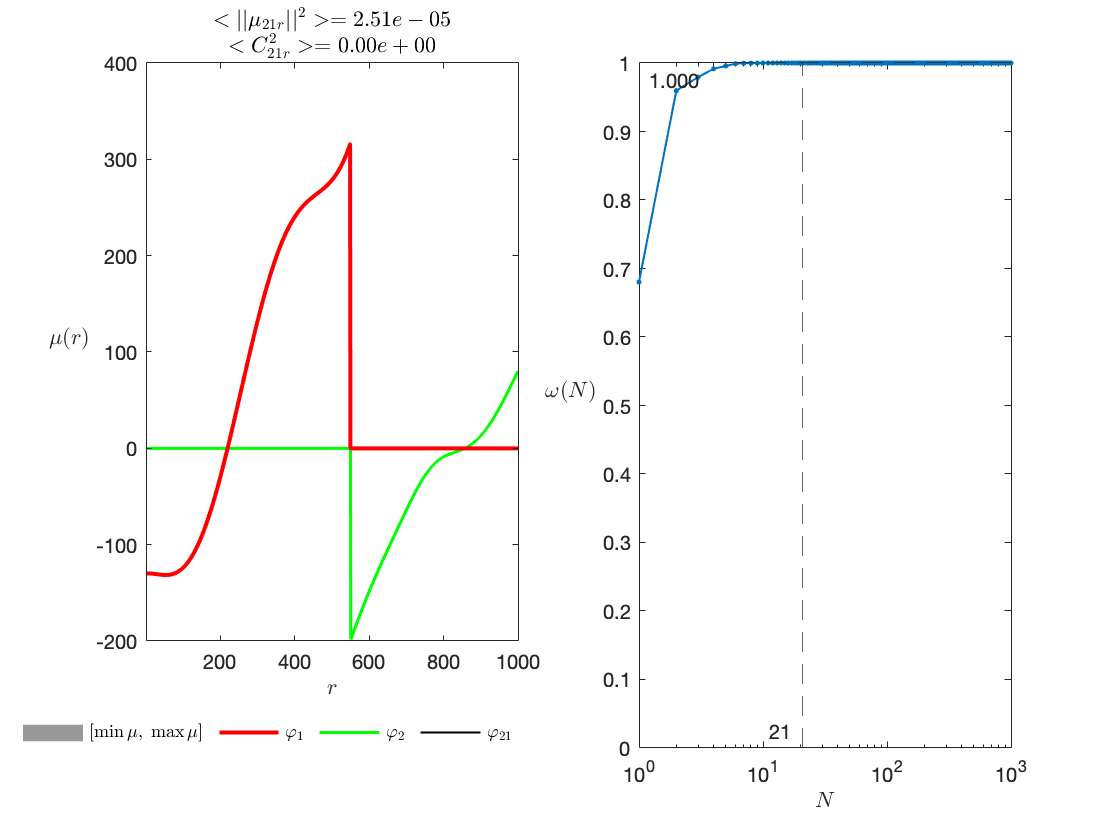

Kov = (U_new-x0) * (U_new-x0)';
Kov(1:q_new,q_new:end) = 0;
Kov(q_new:end,1:q_new) = 0;
Kov(q_new,q_new) = 1;
[U,S,V] = svd(Kov);
S = diag(S);

INTERP.pod = PCA(Kov,21,'init',zeros(Nx,1));
INTERP.pod.x0 = x0;
INTERP.pod.plotSummary(figure(),'data',FOM.X);

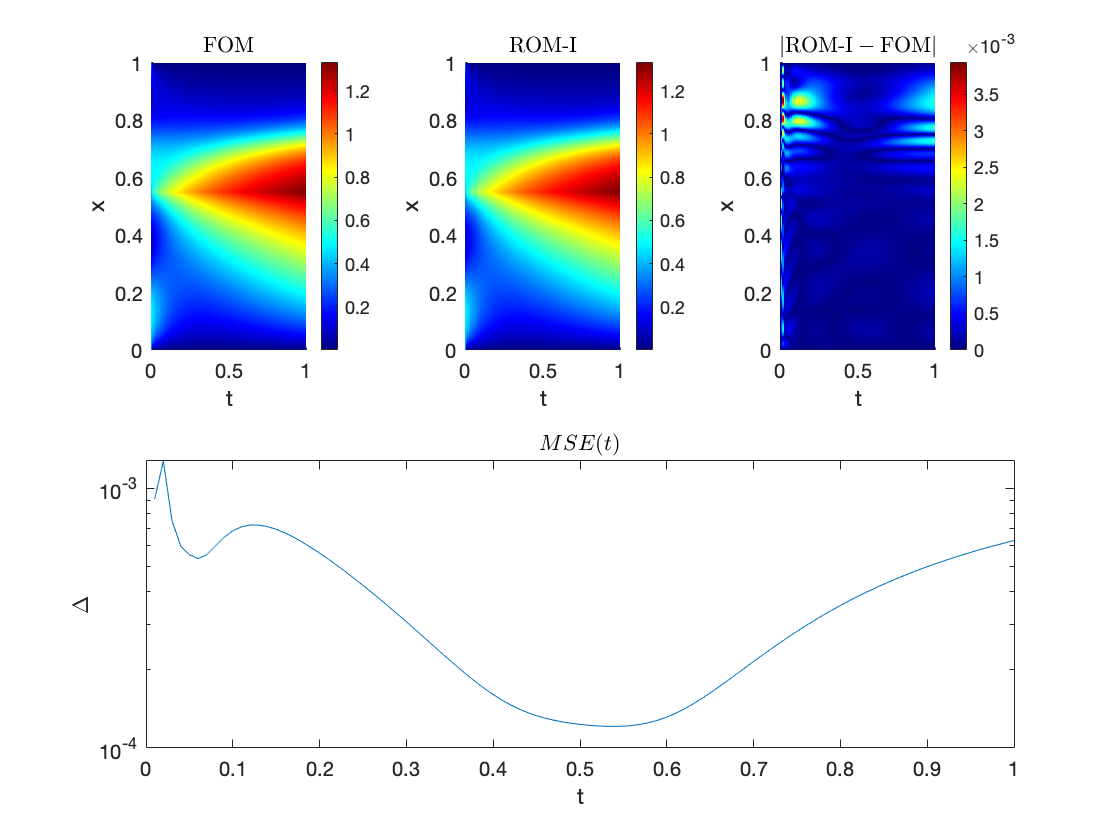

INTERP.encoder = INTERP.pod.genEncoder();
 
INTERP.rom.I = makeROM_I('ROM-I',q_test,INTERP.encoder);

nlin.gauss = @(x,Res,Jac) newton_gauss(x,Res,Jac,newton_param,INTERP.pod.genEncoder().decjac);

INTERP.rom.I = solveDif(T,Nt,INTERP.rom.I,nlin.gauss);
INTERP.rom.I.X = INTERP.pod.decode(INTERP.rom.I.X);
plotComp(figure(),FOM,INTERP.rom.I);

function [scaled] = deform(data,size_new)
    size_old = size(data,1);
    interp_space = griddedInterpolant([1,size_new],[1,size_old]);
    interp_data = griddedInterpolant(1:size_old,data);
    scaled = interp_data(interp_space(1:size_new));
end